# **八木天线的仿真（天线工具箱仿真计算）**

**        八木天线是一种常用于射频通信系统的定向天线，具有高增益和窄波束特性，常用于无线电通信和雷达系统中。 与**[**偶极子天线的仿真**](matlab:open('./G5_Dipole_Antenna_Antenna_Toolbox.mlx'))**类似，本小节使用天线工具箱仿真八木天线。**

- **定义参数：选择VHF（甚高频）波段中心频段为例**

fc = 144.5e6;
wirediameter = 12e-3;
c = physconst('lightspeed');
lambda = c/fc;
Z0 = 50;
BW = 0.015*fc;
fmin = fc - 2*(BW);
fmax = fc + 2*(BW);
Nf = 101;
freq = linspace(fmin,fmax,Nf);

**        可调整偶极子的长度和宽度参数实现较好的效果，本小节宽度是使用天线工具箱中提供的函数计算得到的。在设计频率下，长度选择约为λ/2。**

d = dipole;
d.Length = 0.982.*(lambda/2);
d.Width = cylinder2strip(wirediameter/2);
d.Tilt = 90;
d.TiltAxis = 'Y';

- **设置元素长度和元素间距**

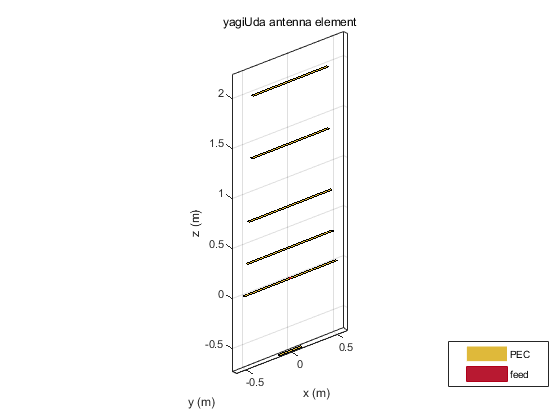

Numdirs = 4;
refLength = 0.25;
dirLength = [0.940 0.910 0.850 0.830];
refSpacing = 0.35;
dirSpacing = [0.15 0.2 0.3 0.3 ];
initialdesign = [refLength refSpacing dirSpacing].*lambda;
yagidesign = yagiUda;
yagidesign.Exciter = d;
yagidesign.NumDirectors = Numdirs;
yagidesign.ReflectorLength = refLength;
yagidesign.DirectorLength = dirLength;
yagidesign.ReflectorSpacing = refSpacing*lambda;
yagidesign.DirectorSpacing = dirSpacing*lambda;
figure
show(yagidesign)
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **绘制辐射图**

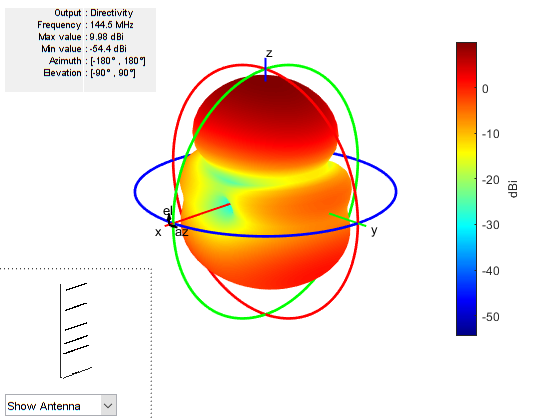

figure
pattern(yagidesign,fc)

- **仿真计算轴比和波瓣宽度**

ar=axialRatio(yagidesign,fc,20,30)        

ar = 34.1417

[bw,angles]=beamwidth(yagidesign,fc,0,1:1:360)         

bw = 52.0000

angles =     64   116


- **仿真计算输入阻抗**

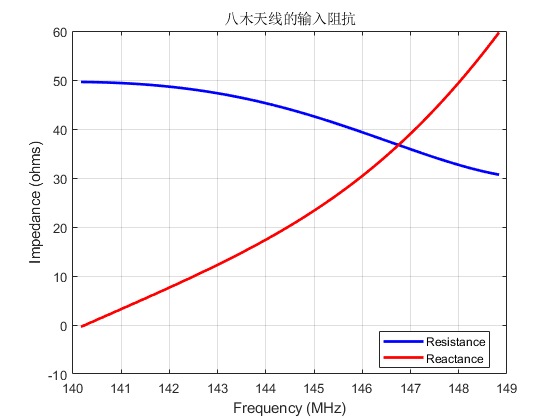

figure
impedance(yagidesign,freq);
title('八木天线的输入阻抗');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真计算反射系数S11**

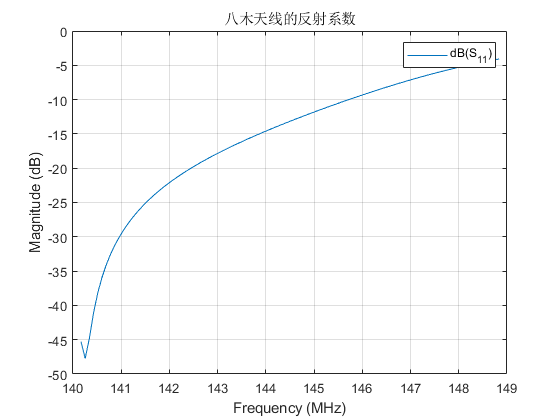

S=sparameters(yagidesign,freq);               %用sparameters函数计算天线的反射系数S11
figure
rfplot(S);
title('八木天线的反射系数');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真计算回波损耗**

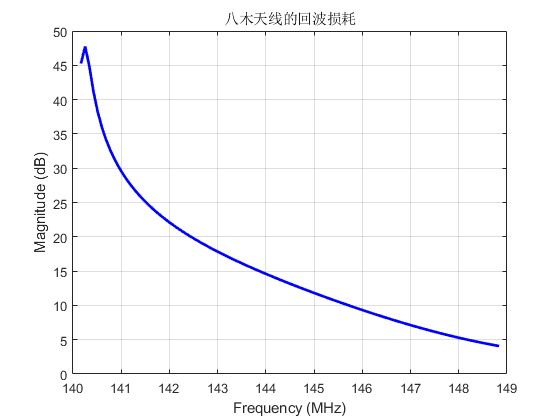

figure
returnLoss(yagidesign,freq);                  %用returnLoss函数计算并绘制天线的回波损耗
title('八木天线的回波损耗');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真计算驻波比**

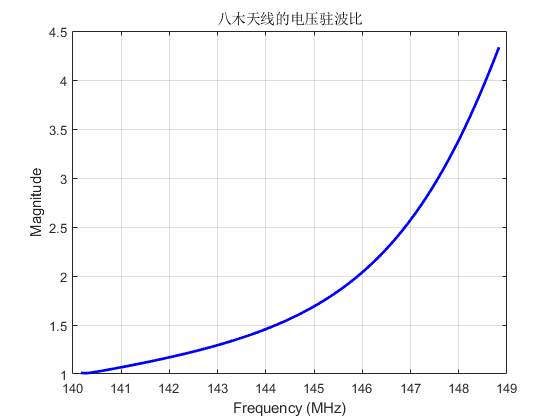

figure
vswr(yagidesign,freq);                        %用vswr函数计算并绘制天线的电压驻波比
title('八木天线的电压驻波比');
set(gcf,'Visible','on');   	    %强制图片弹出显示

## **参考文献：**

        **[1] **[**https://www.mathworks.com/help/antenna/ug/design-optimization-of-a-six-element-yagi-uda-antenna-surrogate-method.html**](https://www.mathworks.com/help/antenna/ug/design-optimization-of-a-six-element-yagi-uda-antenna-surrogate-method.html)